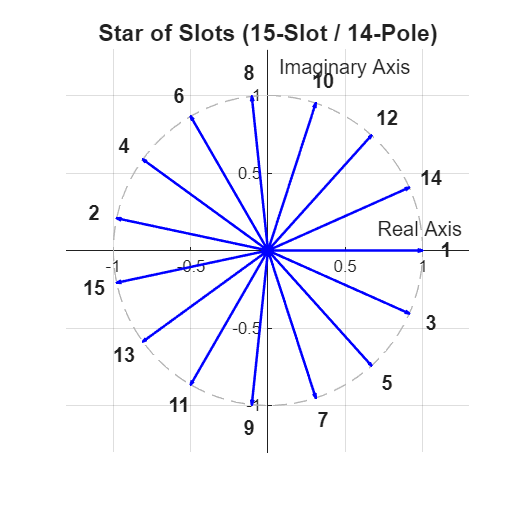

% =========================================================================
% Phasor Diagrams for 15-Slot / 14-Pole PMSM
% Author: Metin Özdemir
% EE568 Project-2
% =========================================================================
clear; clc; close all;

%% ------------------------------------------------------------------------
% FIGURE 1: STAR OF SLOTS (15 Vectors, 168 degrees apart)
% ------------------------------------------------------------------------
Q = 15;
alpha_e = 168; % Electrical angle between adjacent slots in degrees

figure('Name', 'Star of Slots', 'Color', 'w', 'Position', [100, 100, 600, 600]);
hold on; grid on; axis equal;
title('Star of Slots (15-Slot / 14-Pole)', 'FontSize', 14, 'FontWeight', 'bold');

% Draw a dashed background circle for aesthetics
theta_circle = linspace(0, 2*pi, 100);
plot(cos(theta_circle), sin(theta_circle), 'k--', 'Color', [0.7 0.7 0.7]);

% Plot the 15 vectors
for slot = 1:Q
    % Calculate angle for current slot (Slot 1 starts at 0 degrees)
    angle_deg = (slot - 1) * alpha_e;
    angle_rad = deg2rad(angle_deg);
    
    % X and Y components
    u = cos(angle_rad);
    v = sin(angle_rad);
    
    % Draw the vector
    quiver(0, 0, u, v, 0, 'MaxHeadSize', 0.1, 'LineWidth', 1.5, 'Color', 'b');
    
    % Add slot numbers slightly outside the tip of the vector
    text_offset = 1.15;
    text(u * text_offset, v * text_offset, num2str(slot), ...
        'HorizontalAlignment', 'center', ...
        'FontSize', 12, 'FontWeight', 'bold');
end

% Format axes
xlim([-1.3 1.3]); ylim([-1.3 1.3]);
xlabel('Real Axis', 'FontSize', 12);
ylabel('Imaginary Axis', 'FontSize', 12);
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
box off;

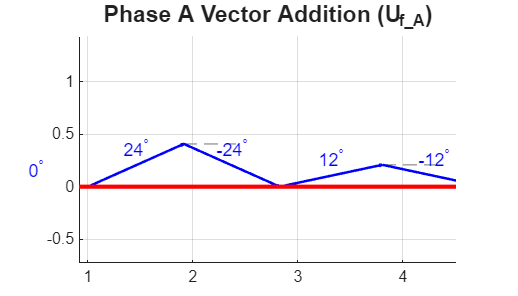


%% ------------------------------------------------------------------------
% FIGURE 2: PHASE A PHASOR DIAGRAM (Tip-to-Tail Vector Addition)
% ------------------------------------------------------------------------
% Ordered to match the hand-drawn zig-zag sequence from your notes
phaseA_angles_deg = [0, 24, -24, 12, -12];

figure('Name', 'Phase A Tip-to-Tail', 'Color', 'w', 'Position', [750, 100, 700, 400]);
hold on; grid on; axis equal;
title('Phase A Vector Addition (U_{f\_A})', 'FontSize', 14, 'FontWeight', 'bold');

current_x = 0;
current_y = 0;

% Plot the 5 individual Phase A vectors tip-to-tail
for i = 1:length(phaseA_angles_deg)
    ang_rad = deg2rad(phaseA_angles_deg(i));
    u = cos(ang_rad);
    v = sin(ang_rad);
    
    % Draw individual vector starting from the tip of the last one
    quiver(current_x, current_y, u, v, 0, 'MaxHeadSize', 0.1, 'LineWidth', 1.5, 'Color', 'b');
    
    % Label the angles near each vector
    text(current_x + u/2, current_y + v/2 + 0.15, sprintf('%d^\\circ', phaseA_angles_deg(i)), ...
        'HorizontalAlignment', 'center', 'FontSize', 11, 'Color', 'b');
    
    % Add a dashed horizontal reference line at each joint (like the sketch)
    if i < length(phaseA_angles_deg)
        plot([current_x + u, current_x + u + 0.5], [current_y + v, current_y + v], ...
            'k--', 'Color', [0.6 0.6 0.6]);
    end
    
    % Update starting point for the next vector
    current_x = current_x + u;
    current_y = current_y + v;
end

% Plot the Resultant Vector from origin to the final tip
quiver(0, 0, current_x, current_y, 0, 'MaxHeadSize', 0.05, 'LineWidth', 2.5, 'Color', 'r');

text(current_x/2, current_y - 0.25, 'Color', 'r', 'FontSize', 12, 'FontWeight', 'bold');

Error using text
Invalid parameter/value pair arguments


% Format axes
xlim([-0.5, current_x + 0.5]); ylim([-1, 1.5]);
xlabel('Real Axis', 'FontSize', 12);
ylabel('Imaginary Axis', 'FontSize', 12);
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
box off;